clear
clf
%Loaded data ind og laver lidt omskrives/splitter dem ud. 
data=load("Measurements\Measurements1.csv")

data = 1.0e+05 *

    2.9747         0         0   -0.0000    0.0013
    2.9754   -0.0000         0   -0.0000    0.0013
    2.9762         0         0   -0.0000    0.0013
    2.9770         0         0   -0.0000    0.0013
    2.9777   -0.0000         0   -0.0000    0.0013
    2.9785         0         0   -0.0000    0.0013
    2.9793         0         0   -0.0000    0.0013
    2.9800         0         0   -0.0000    0.0013
    2.9808         0         0   -0.0000    0.0013
    2.9816         0         0   -0.0000    0.0013


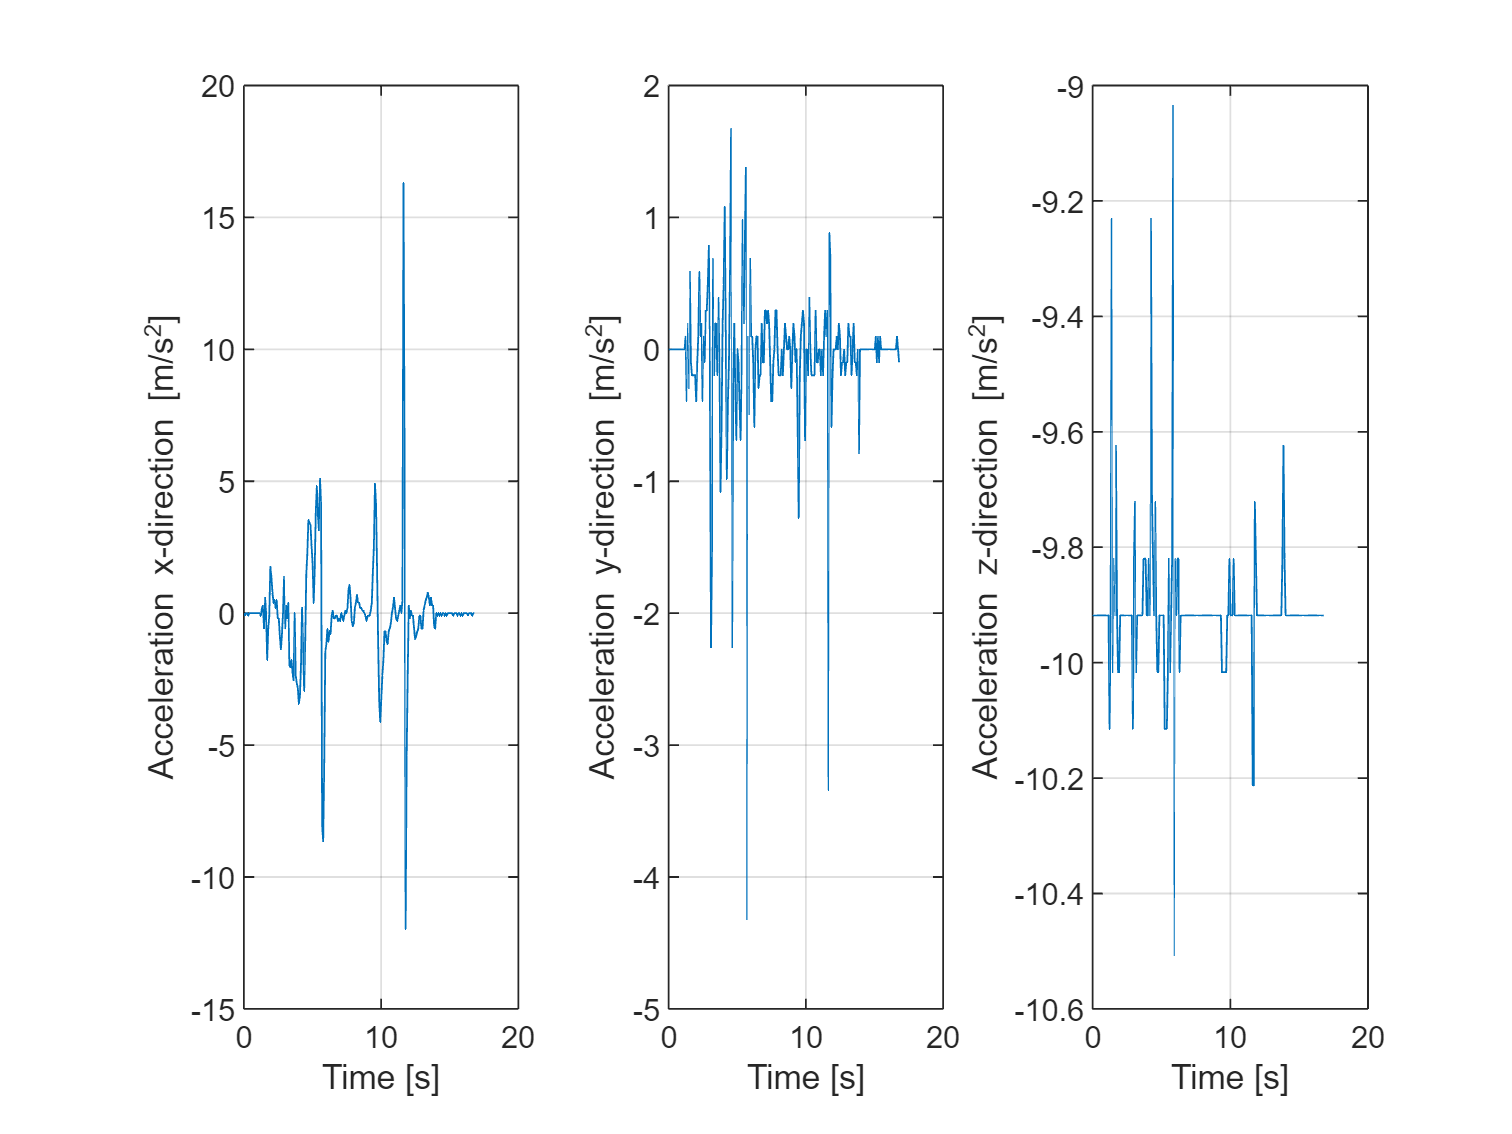


Time=(data(:,1)-data(1,1))/1000; %Tid nulstiller og omregner til sekunder. 
Acc=data(:,2:4)*9.82; %Omregning fra g til m/s^2 for acceleration. 
D_object=data(:,end)/1000;  %Afstanden til objektet og omregne til meter



%Plotting the data
figure(27)
subplot(1,3,1);
plot(Time,Acc(:,1))
xlabel("Time [s]")
ylabel("Acceleration x-direction [m/s^2]")
grid
subplot(1,3,2); 
plot(Time,Acc(:,2))
xlabel("Time [s]")
ylabel("Acceleration y-direction [m/s^2]")
grid
subplot(1,3,3); 
plot(Time,Acc(:,3))
xlabel("Time [s]")
ylabel("Acceleration z-direction [m/s^2]")
grid

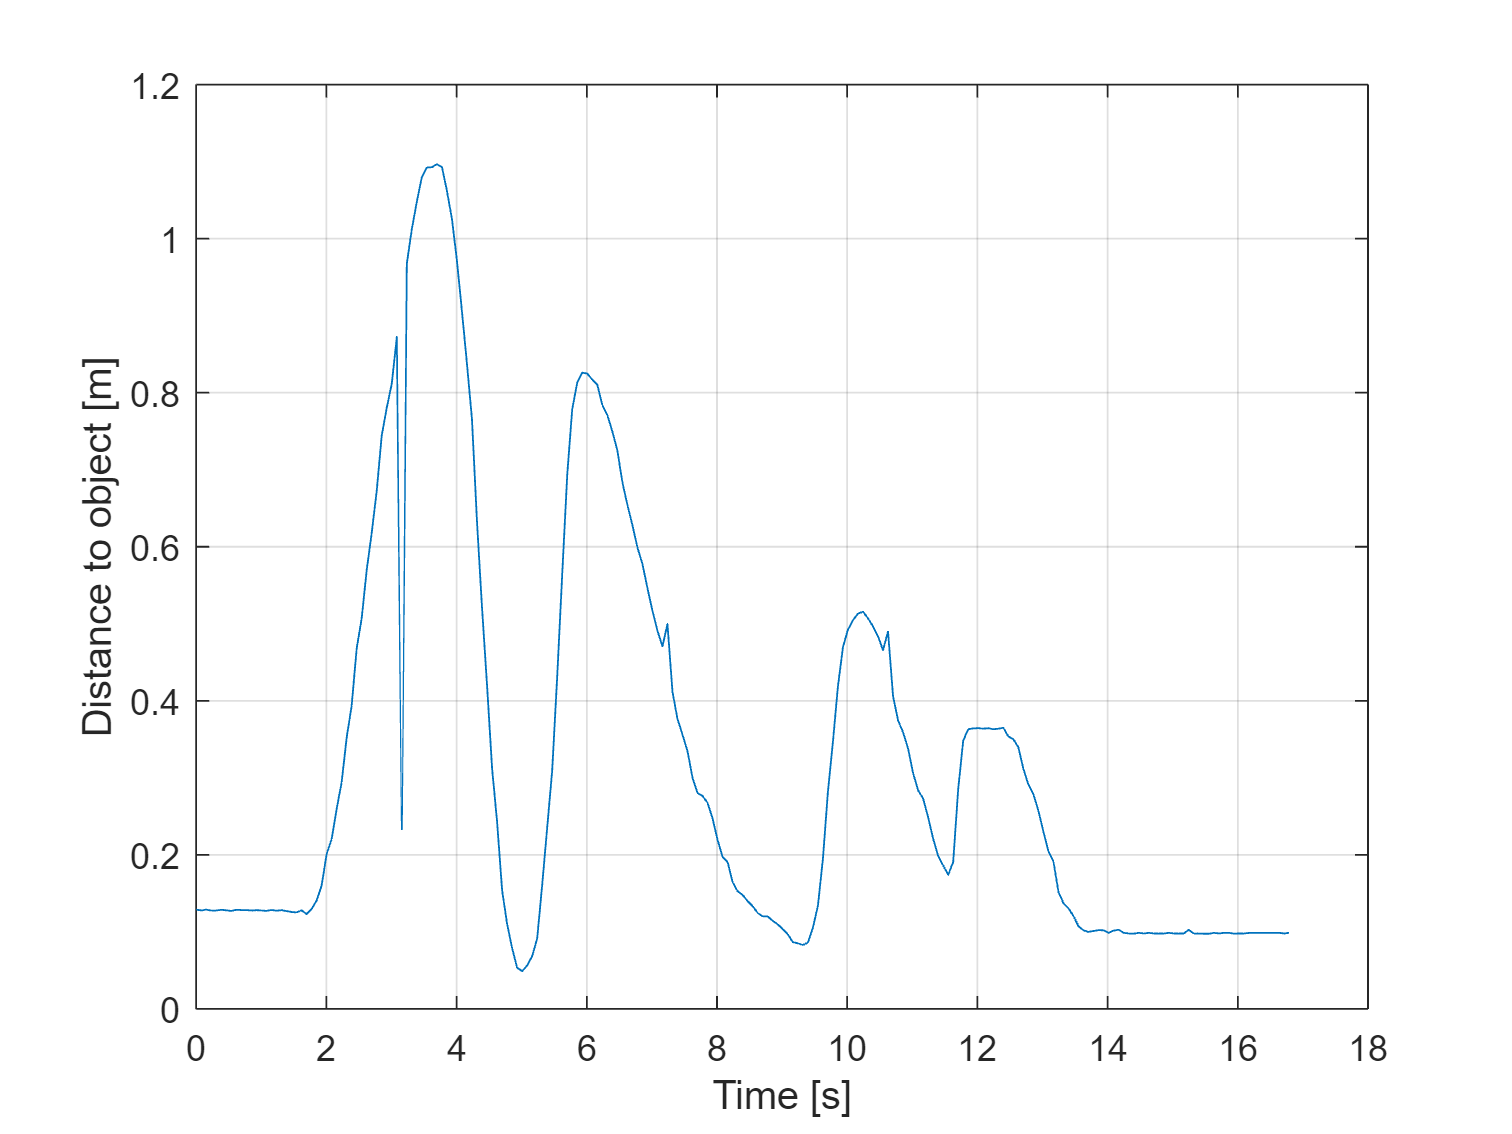


figure(28)
plot(Time,D_object)
xlabel("Time [s]")
ylabel("Distance to object [m]")
grid


%Model representation: 
phi=0.99;
Ts=0.077; 
Phi= [phi,0,0,0;Ts,1,0,0;0,Ts,1,0;0,0,0,1]

Phi =     0.9900         0         0         0
    0.0770    1.0000         0         0
         0    0.0770    1.0000         0
         0         0         0    1.0000


%Phi=Phi(1:3,1:3)
H= [1,0,0,1;0,0,1,0];
%H=H(:,1:3)
%Measurement noise
Ra=0.17^2;  
Rp=0.7/(1000^2);

R=[Ra,0;0,Rp]

R =     0.0289         0
         0    0.0000




Q_a=0.0419^2;  

Q=[Q_a,0,0,0;0,0,0,0;0,0,0,0;0,0,0,0]

Q =     0.0018         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


%Q=Q(1:3,1:3)





%Making a few definition  (of zeros) before the for loop for the Kalman filter. 
N_samples=length(data);
N_states=size(Phi,1);
N_outputs=size(H,1);

%Kalman gian: 
K=zeros(N_states,N_outputs,N_samples); 
% Estimation error: 
y_error=zeros(N_outputs,N_samples); 

yp= zeros(N_outputs,N_samples); % prediction for output p=prediction thereby k|k-1 


xe= zeros(N_states,N_samples); %estimation of state E for estimation thereby k|k
xp= zeros(N_states,N_samples); %prediction for states, p=prediction. thereby k|k-1

%Making a matrix with the measured data,

measured=[Acc(:,1)';D_object'];

% Initialising
%Position=distance to object therefore takning the first one out. 
x0=[0;0;0;0]; 
%x0=x0(1:3,1)
P0= eye(N_states)*0.1; 



%Initlaxation values for the Kalman filter
xp(:,1)= x0; 
Pp= P0;
% Kalman filter. 
for i= 1:N_samples
  % Measurement update
  %Predite the output
  yp(:,i)= H*xp(:,i); 
  
  %Estimation error: %Update when data is avable
  y_error=measured(:,i)-yp(:,i); 
  %Kalman gain:
  K(:,:,i)= Pp*H'*inv((H*Pp*H'+R)); 
  %estimation of x: 
  xe(:,i)= xp(:,i)+K(:,:,i)*(y_error); 
  %Covaraince of error estimation: 
  Pe= (eye(N_states)-K(:,:,i)*H)*Pp*(eye(N_states)-K(:,:,i)*H)'+K(:,:,i)*R*K(:,:,i)';

  % Time update
  xp(:,i+1)= Phi*xe(:,i);
  Pp= Phi*Pe*Phi'+Q;
end


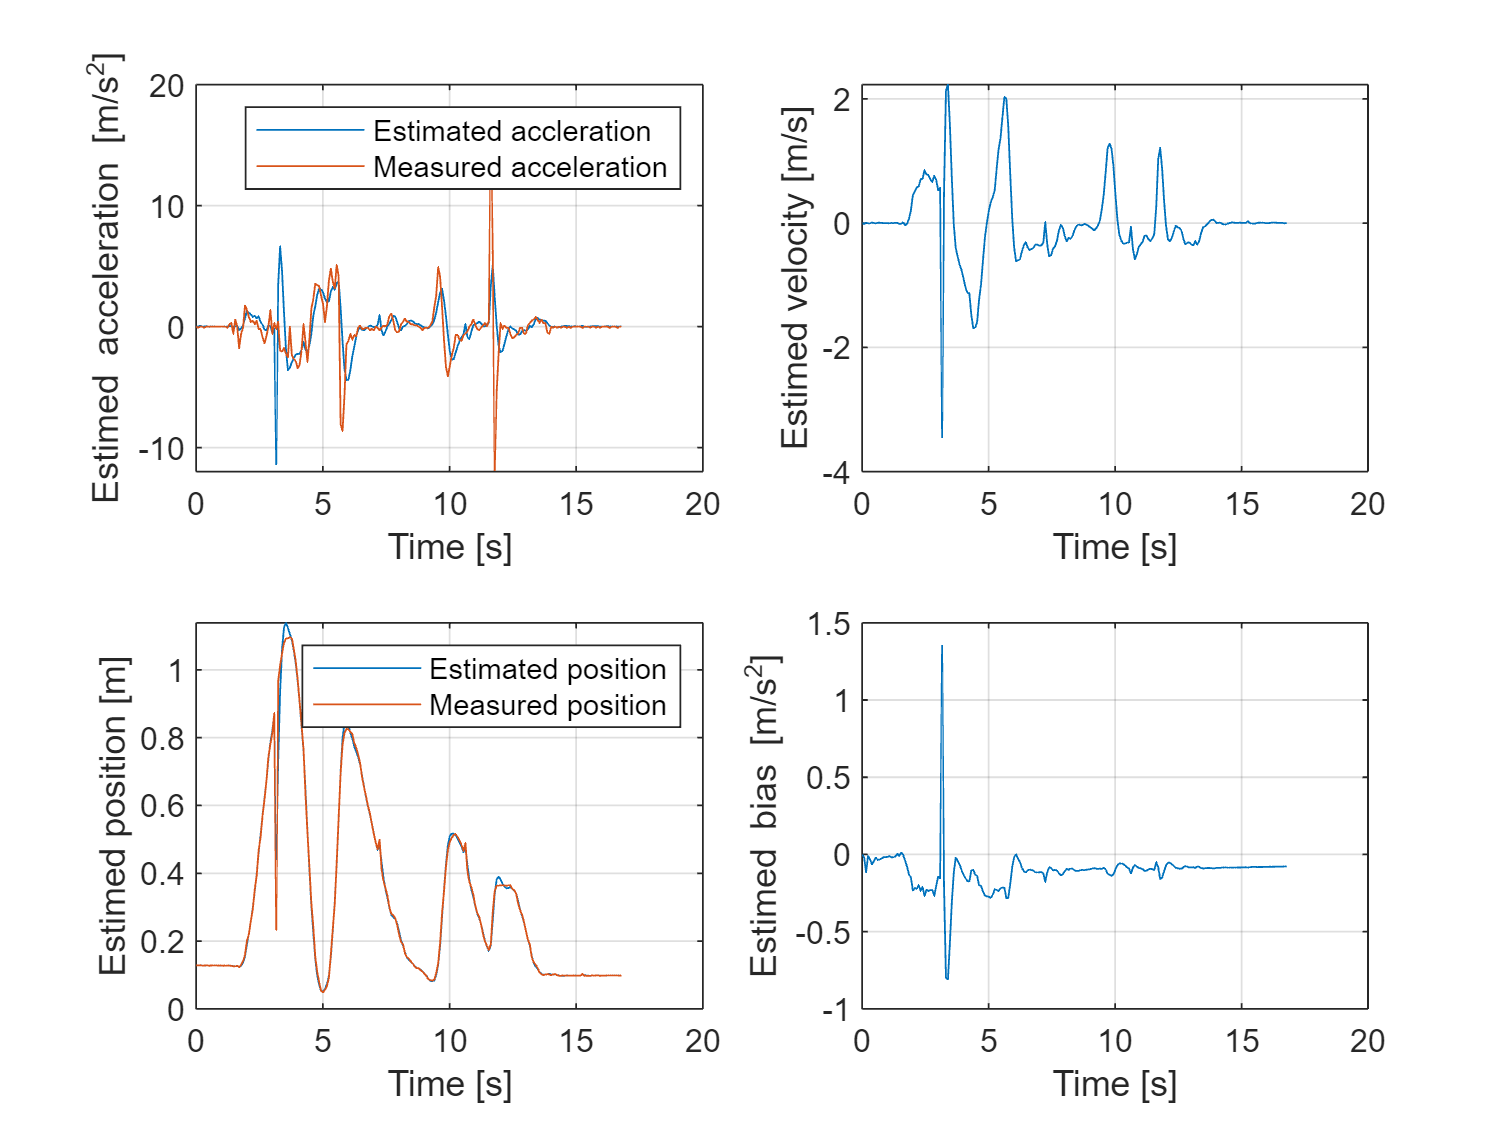

%Plotter alle estimationer af states altså x(k|k), for ens kalman filter: 
figure(29)
subplot(2,2,1)
plot(Time,xe(1,:))
hold on 
plot(Time,Acc(:,1))
hold off 
legend("Estimated accleration","Measured acceleration")

xlabel("Time [s]")
ylabel("Estimed acceleration [m/s^2]")
grid 
subplot(2,2,2)
plot(Time,xe(2,:))
xlabel("Time [s]")
ylabel("Estimed velocity [m/s]")
grid
subplot(2,2,3)
plot(Time,xe(3,:))
hold on 
plot(Time,D_object)
hold off
xlabel("Time [s]")
ylabel("Estimed position [m]")
legend("Estimated position","Measured position")
grid 
subplot(2,2,4)
plot(Time,xe(4,:))
xlabel("Time [s]")
ylabel("Estimed bias [m/s^2]")
grid

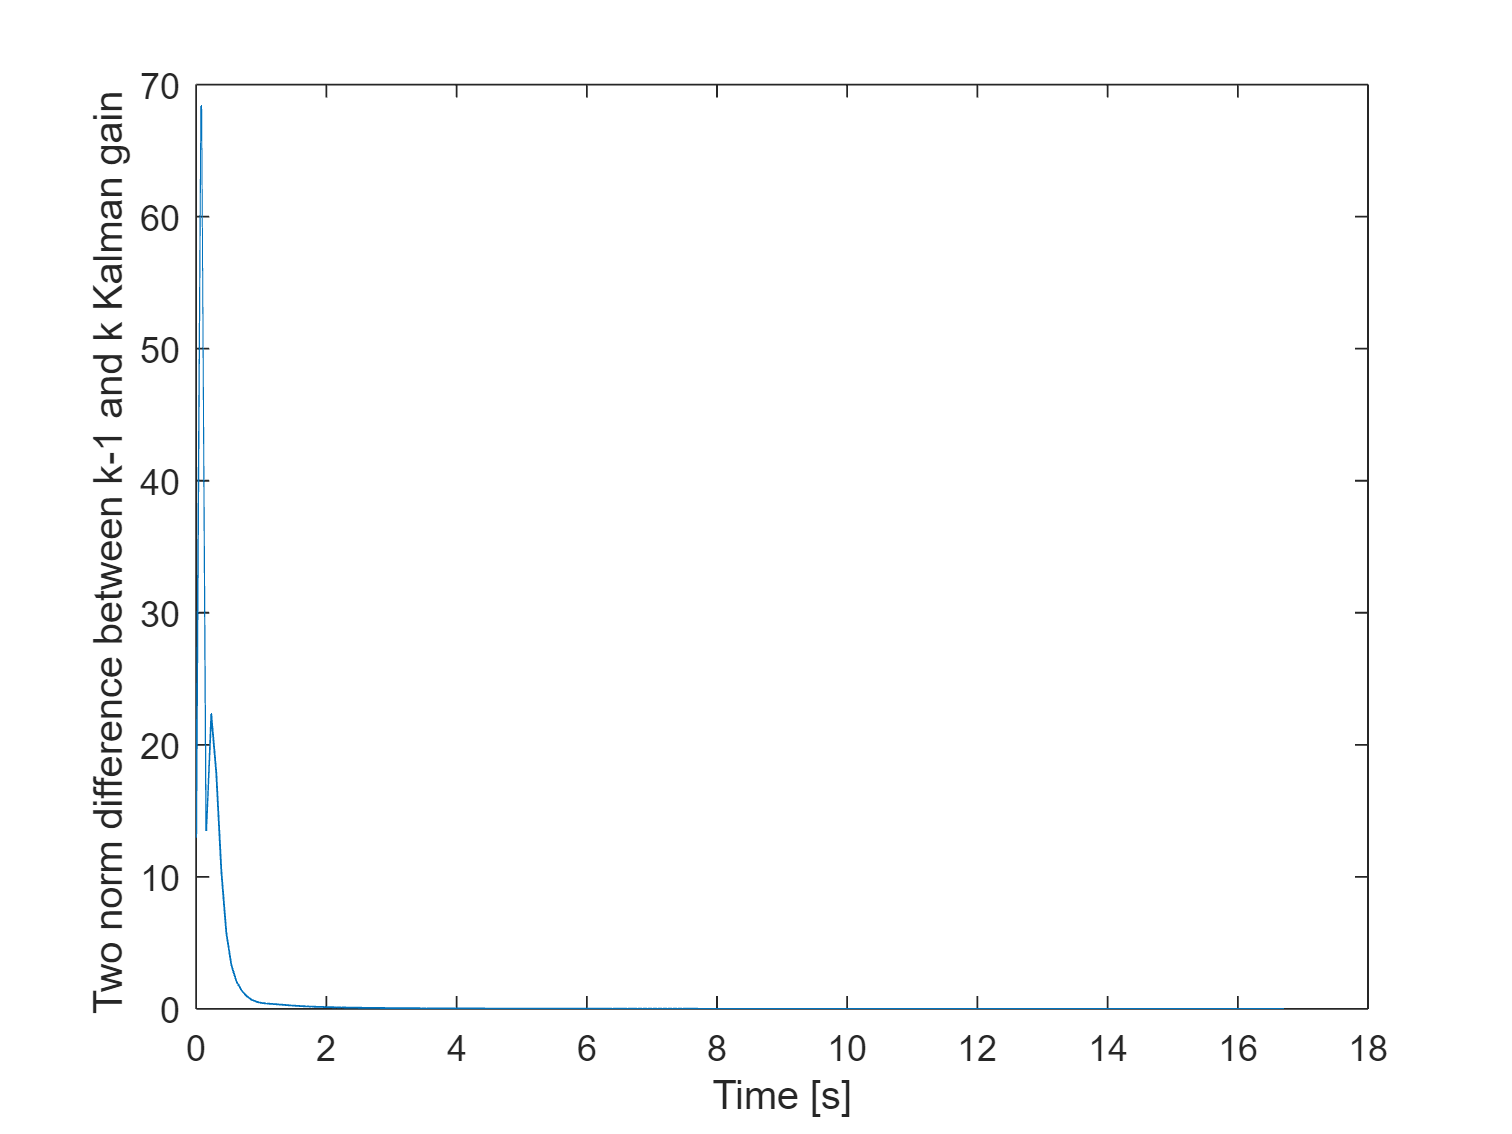

%Tager 2-normen af difference i mmellem k og k-1 i kalman gain 
Difference=zeros(1,N_samples-1);
for i=1:N_samples-1 
    Difference(1,i)=norm(K(:,:,i+1)-K(:,:,i),2);
end 

figure(30)
plot(Time(1:end-1,1),Difference)
xlabel("Time [s]")
ylabel("Two norm difference between k-1 and k Kalman gain ")

%Tager halv halv i mellem integral af acceleration og afledt af position
%ændring for at sammenligne med Kalman filter 
velocity=zeros(1,N_samples)

velocity =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


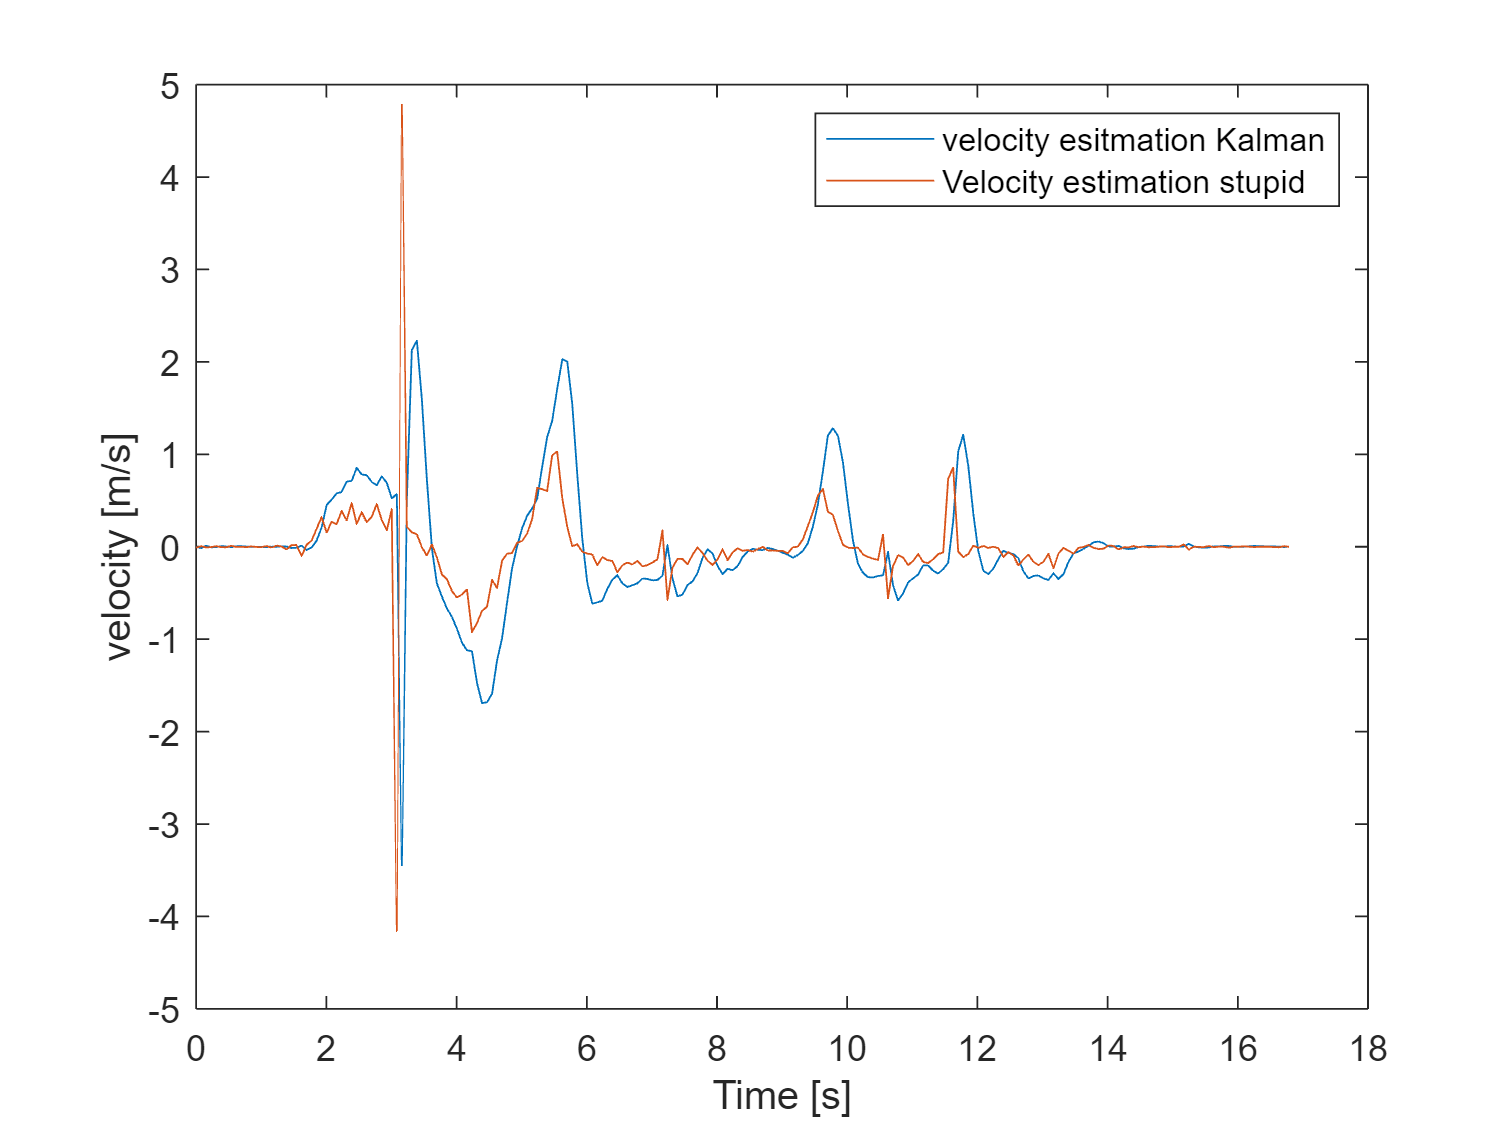

for i=2:N_samples
    velocity(1,i-1)=((Acc(i,1)*Ts)+(D_object(i,1)/Ts-D_object(i-1,1)/Ts))*0.5;
end 

figure(40)
plot(Time,xe(2,:))
hold on 
plot(Time,velocity)
hold off
xlabel("Time [s]") 
ylabel("velocity [m/s]")
legend("velocity esitmation Kalman","Velocity estimation stupid")

y_error_k=zeros(N_outputs,N_samples); 

yp_k= zeros(N_outputs,N_samples); % prediction for output p=prediction thereby k|k-1 


xe_k= zeros(N_states,N_samples); %estimation of state E for estimation thereby k|k
xp_k= zeros(N_states,N_samples); %prediction for states, p=prediction. thereby k|k-1

%Making a matrix with the measured data,

measured=[Acc(:,1)';D_object'];

% Initialising
%Position=distance to object therefore takning the first one out. 
x0=[0;0;D_object(1,1);0]; 
%x0=x0(1:3,1)
P0= eye(N_states)*0.1; 



%Initlaxation values for the Kalman filter
xp_k(:,1)= x0; 
Pp= P0;
% Kalman filter. 
for i= 1:N_samples
  % Measurement update
  %Predite the output
  yp_k(:,i)= H*xp_k(:,i); 
  
  %Estimation error: %Update when data is avable
  y_error_k=measured(:,i)-yp_k(:,i); 

  %estimation of x: 
  xe_k(:,i)= xp_k(:,i)+round(K(:,:,219),2)*(y_error_k); 

  % Time update
  xp_k(:,i+1)= Phi*xe_k(:,i);
end


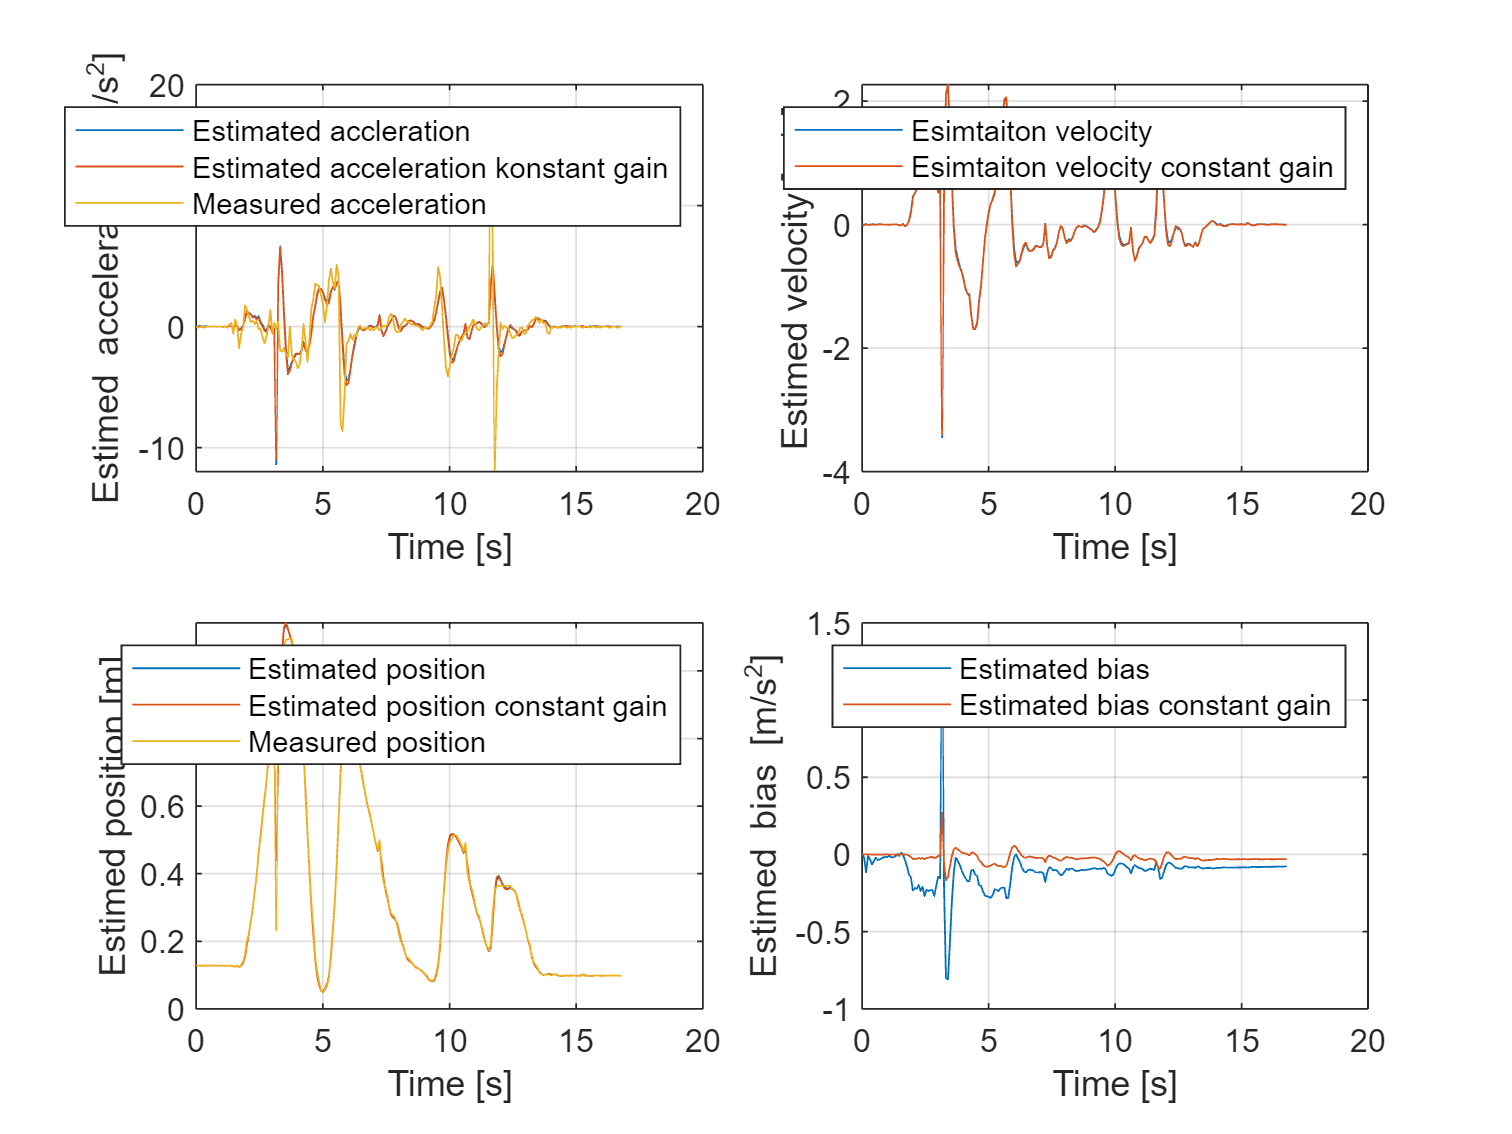

figure(29)
subplot(2,2,1)
plot(Time,xe(1,:))
hold on 
plot(Time,xe_k(1,:))
plot(Time,Acc(:,1))
hold off 
legend("Estimated accleration","Estimated acceleration konstant gain","Measured acceleration")

xlabel("Time [s]")
ylabel("Estimed acceleration [m/s^2]")
grid 
subplot(2,2,2)
plot(Time,xe(2,:))
hold on 
plot(Time,xe_k(2,:))
hold off 
xlabel("Time [s]")
ylabel("Estimed velocity [m/s]")
legend("Esimtaiton velocity","Esimtaiton velocity constant gain")
grid
subplot(2,2,3)
plot(Time,xe(3,:))
hold on 
plot(Time,xe_k(3,:))
plot(Time,D_object)
hold off
xlabel("Time [s]")
ylabel("Estimed position [m]")
legend("Estimated position","Estimated position constant gain","Measured position")
grid 
subplot(2,2,4)
plot(Time,xe(4,:))
hold on
plot(Time,xe_k(4,:))
hold off
xlabel("Time [s]")
ylabel("Estimed bias [m/s^2]")
legend("Estimated bias","Estimated bias constant gain")
grid